# EEE3548 Exercise #5 Phase contrast microscopy

## [Insert your ID HERE] [Insert your name HERE]

#### Q1. Define an object with complex transmittance. Suppose that 2 objects with specific shape(circle, rectangle...) are in the water, one has only transmittance of 0.8 and the other has only phase(thickness of 500 nm, refractive index(RI) of the object is 1.38). Plot the amplitude and phase seperately of the objects. (Set the pixel size is 100 nm, Number of the pixels is 256, wavelength as 500 nm, refractive index of media is 1.33).

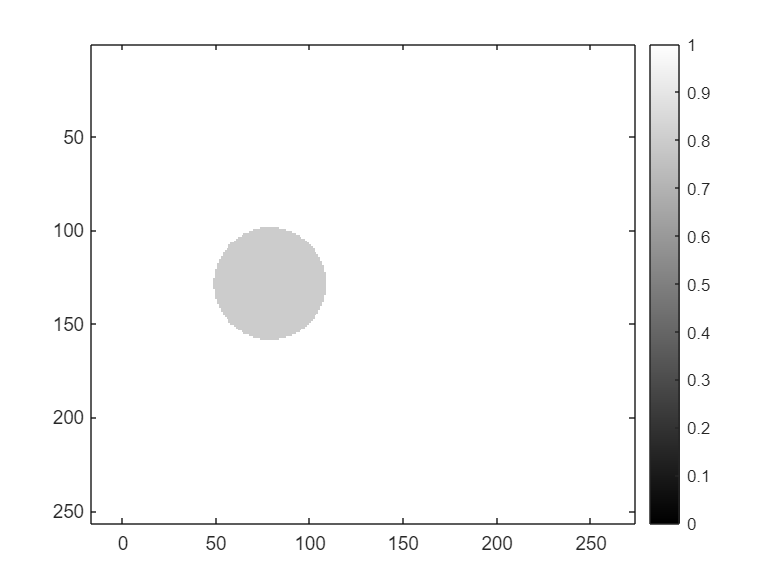

N = 256;            % number of pixel = 256
psize = 100 * 10^-9;      % pixel size = 100nm
lambda = 500*10^-9;       % wavelength = 500nm

X = linspace(-1/2, 1/2, N) * N * psize;  % x-axis
Y = linspace(-1/2, 1/2, N) * N * psize;  % y-axis
[x,y] = meshgrid(X,Y);

n = 1.38;       % refractive index of the object = 1.38
n_water = 1.33; % refractive index of media = 1.33
d = 500 * 10^-9;% thickness = 500nm


r = 3 * 10^-6;  % circle(specific shape) radius 

Amp = ones(N,N);
Amp( (x + 50*10^-7).^2 + y.^2 <= r^2 ) = 0.8; % one has only transmittance of 0.8
Phase = ones(N,N);                           
Phase( (x - 50*10^-7).^2 + y.^2 <= r^2 ) = 1 * exp(j * (2 * pi / lambda) * (n - n_water) * d);   % the other has only phas

obj = ones(N,N);
obj = Amp.*Phase; % multiple amp one and phase one to arrange both in one space

imagesc(abs(obj), [0 1]);colorbar;colormap gray;axis equal; % plot amplitude 

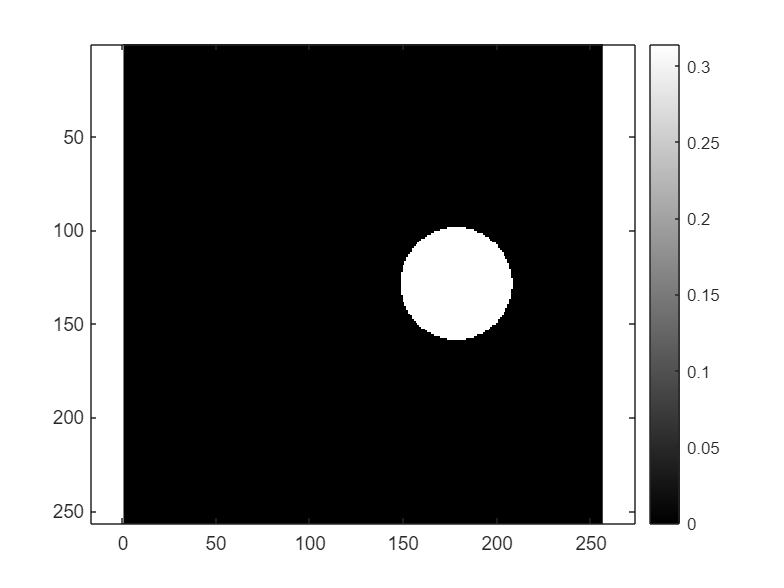

imagesc(angle(obj));colorbar;colormap gray;axis equal;   % plot phase

#### Q2. Define an ideal optical transfer function(OTF) with NA=0.5. (Use cut-off frequency $k_c =\frac{\textrm{NA}}{\lambda }$). Also, Plot the OTF.

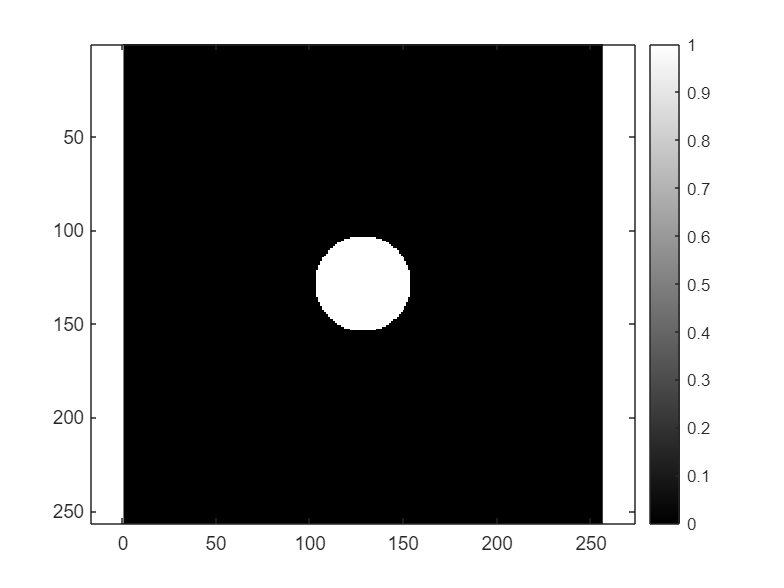

N = 256;            % number of pixel = 256
psize = 100 * 10^-9;      % pixel size = 100nm
lambda = 500 * 10^-9;       % wavelength = 500nm

x = linspace(-1/2, 1/2, N) / psize ;  % x-axis
y = linspace(-1/2, 1/2, N) / psize ;  % y-axis
[k_x,k_y] = meshgrid(x,y);

k_c = 0.5/lambda;  %k_c= NA/lambda                    

H = zeros(N,N);
H( k_x.^2 + k_y.^2 <= k_c^2 ) = 1;        % create ideal OTF
imagesc(abs(H));colorbar;colormap gray;axis equal;   % plot the OTF

#### Q3. Image the object from Q1. Plot the intensity of the result image.

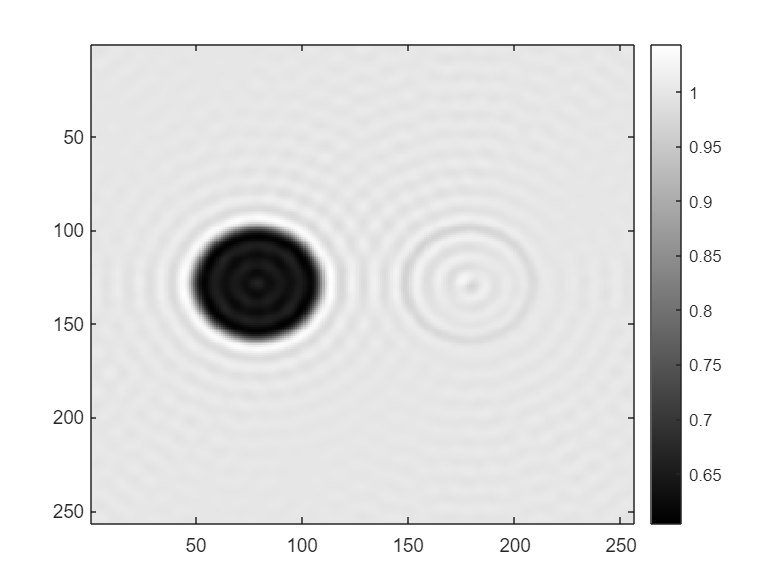

A = fftshift(fft2(obj)).*H;    
Intensity = abs((ifft2(ifftshift(A)))).^2;
imagesc(Intensity);colorbar; % plot the intensity of the result image

#### Q4. Simulate the phase contrast microscopy image with custom OTF. Set the amplitue with a concentric circle, outer NA=0.5 and inner NA=0.01, at which the outer area has amplitude of 1 and the inner has 0.2. Also the phase has circle shape with NA=0.01, with phase $\pi/2$ . Plot the amplitude and phase of the OTF, and plot the intensity image of the sample. Compare the result with Q3.

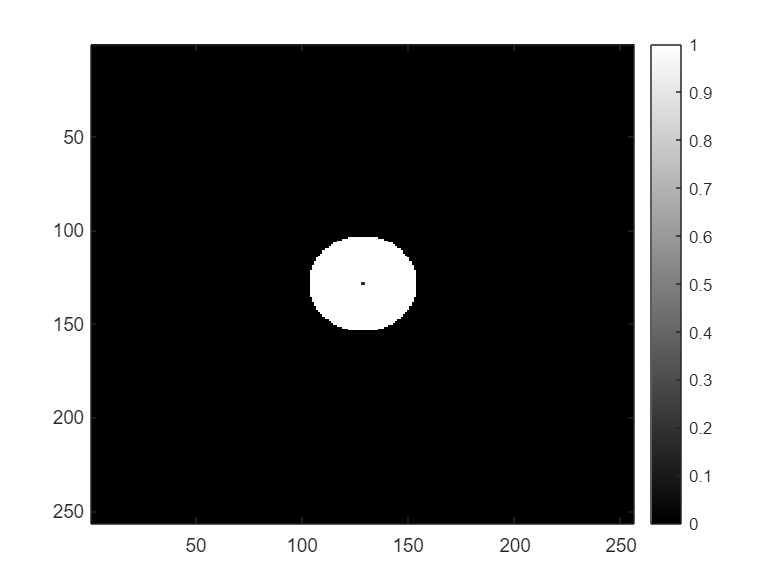

N = 256;            % N = 256
psize = 100 * 10^-9;      % pixel size = 100nm
lambda = 500 * 10^-9;       % wavelength = 500nm

x = linspace(-1/2, 1/2, N) / psize ;  % x-axis
y = linspace(-1/2, 1/2, N) / psize ;  % y-axis
[k_x,k_y] = meshgrid(x,y);

k_c1 = 0.5/lambda;                %k_c1= NA_1/lambda        
k_c2 = 0.015/lambda;              %k_c2= NA_2/lambda  -> 실험에서 circle을 다르게 설계해서 phase contrast가 잘 나타나지 않음-> inner circle을 조금 키웠다.
            
Abs_H = zeros(N,N);
Abs_H( k_x.^2 + k_y.^2 <= k_c1^2) = 1;         % amplitue with a concentric circle, outer NA=0.5, at which the outer area has amplitude of 1
Abs_H( k_x.^2 + k_y.^2 <= k_c2^2) = 0.2;       % amplitue with a concentric circle, outer NA=0.015, at which the outer area has amplitude of 1

Phase_H = ones(N,N);
Phase_H( k_x.^2 + k_y.^2 <= k_c2^2) = 1 * exp(j * ( (pi /2) ));  % the phase has circle shape with NA=0.015, with phase pi/2
H2 = Abs_H.*Phase_H;
imagesc(abs(H2));colorbar;

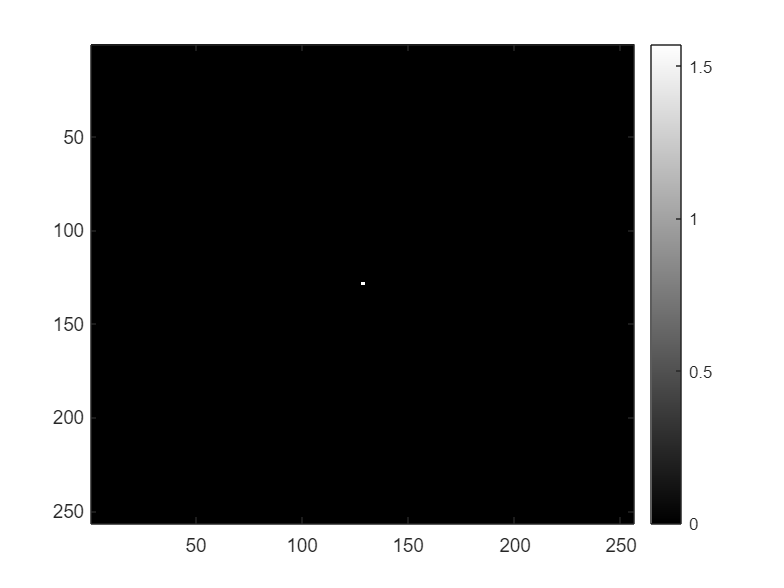

imagesc(angle(H2));colorbar;

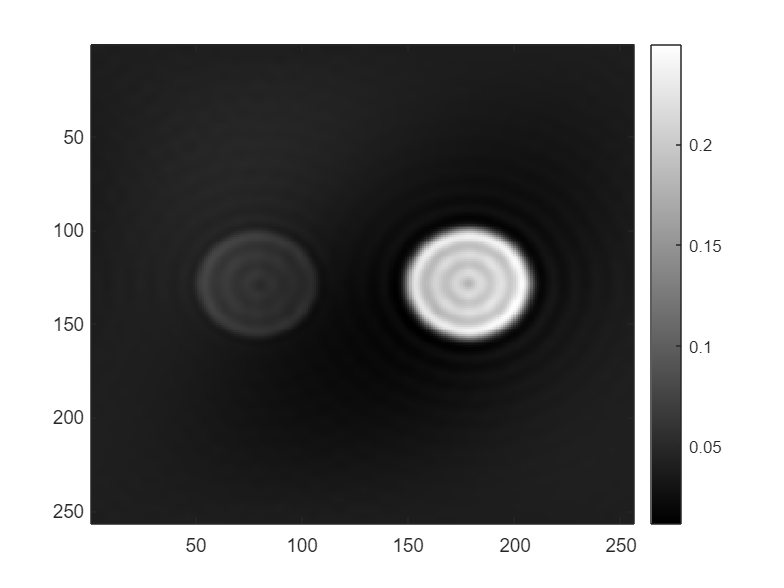

A = fftshift(fft2(obj)).*H2;
Intensity2 = (abs(ifft2(ifftshift(A)))).^2;

imagesc((Intensity2));colorbar; % plot the intensity of the result image

먼저, 실험에서, 총 256개의 pixel로 실험을 진행하였고, inner circle이 0.01인 문제 조건에서, k_x.^2 + k_y.^2 <= k_c2^2를 만족하는 k_x, k_y가 없는 문제를 발견하였다. 이는 pixel을 짝수개로 진행하여서, 중심 축이 없기 떄문으로 생각되고, 따라서 임의로  inner circle이 0.015로 수정하여 실험을 진행하였다.

이를 통해 나온 결과를 확인해보면, 3번문제와 차이점이 있는데, Q3은 amplitude 즉, transparancy에 의한 차이만 구별이 잘 되고, 물질이 달라서 생기는 phase의 차이로 인한  부분은 잘 구분이 되지 않는 것을 확인할 수 있다.

이러한 문제를 해결하기 위한 방법이 phase contrast microscopy이고,  custom OTF를 중간 과정에 넣어주면, 4번 결과처럼, transparancy에 의한 amplitude 차이도 구별이 잘되고, 물질이 달라서 생기는 phase의 차이로 인한  부분 또한 구별이 잘 잘 되는 것을 확인할 수 있다.

따라서,  phase contrast microscopy를 이용하면, 투명한 물질을 관찰할때에도, phase 차이를 이용하여 더 명확하게 물질을 구분할 수 있을 것이다.